## `Задание 1. Свободное движение`

mdl = "task_1";
open_system(mdl);
simIn = Simulink.SimulationInput(mdl);

a0 = 4.5; a1 = 4.5; iy = 1; idy = 0;
out1 = sim(simIn);

a0 = 101.44; a1 = 2.4;
out2 = sim(simIn);

a0 = 100; a1 = 0;
out3 = sim(simIn);

a0 = 101.44; a1 = -2.4; iy = 0.05;
out4 = sim(simIn);

a0 = 4.5; a1 = -4.5;
out5 = sim(simIn);

a0 = -0.64; a1 = 0; iy = 0; idy = 0.1;
out6 = sim(simIn);

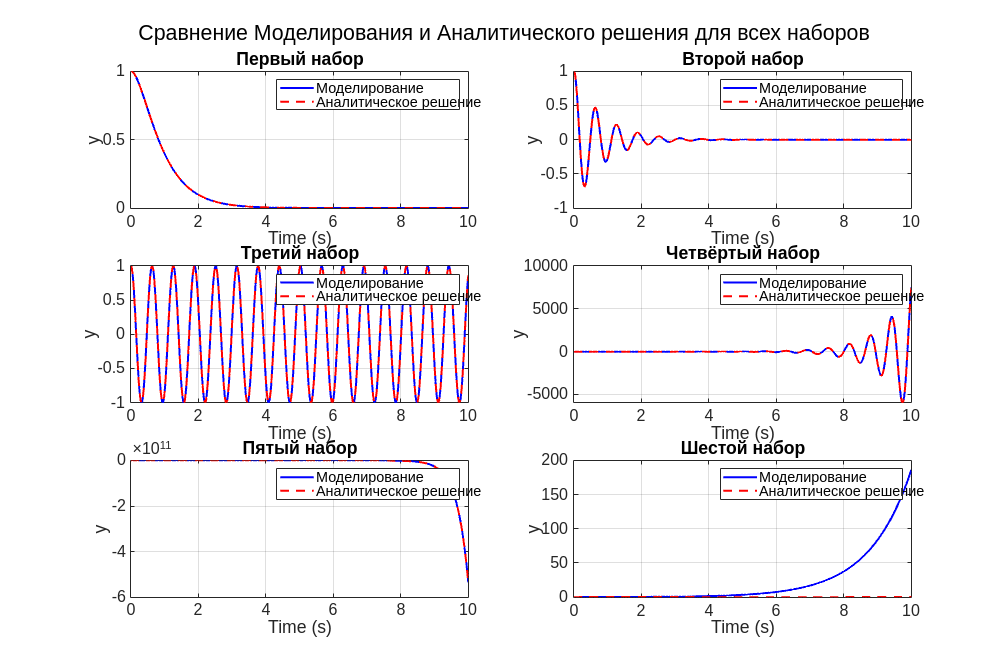

res1 = get(out1, "yout");
res2 = get(out2, "yout");
res3 = get(out3, "yout");
res4 = get(out4, "yout");
res5 = get(out5, "yout");
res6 = get(out6, "yout");

y1 = res1{1}.Values.Data;
y2 = res2{1}.Values.Data;
y3 = res3{1}.Values.Data;
y4 = res4{1}.Values.Data;
y5 = res5{1}.Values.Data;
y6 = res6{1}.Values.Data;

t1 = out1.tout;
t2 = out2.tout;
t3 = out3.tout;
t4 = out4.tout;
t5 = out5.tout;
t6 = out6.tout;

y1a = 2*exp(-1.5*t1) - exp(-3*t1);                     % Formula for y1a
y2a = exp(-1.2*t2).*cos(10*t2) + exp(-1.2*t2).*sin(10*t2)*0.12;  % Formula for y2a
y3a = cos(10*t3);                                      % Formula for y3a
y4a = exp(1.2*t4).*(0.05*cos(10*t4) - 0.006*sin(10*t4)); % Formula for y4a
y5a = -0.05*exp(3*t5) + 0.1*exp(1.5*t5);               % Formula for y5a
y6a = 0.125*sin(0.8*t6);                               % Formula for y6a

% Create a figure
figure;

% Subplot 1: y1 and y1a
subplot(3, 2, 1);
plot(t1, y1, 'b', 'LineWidth', 1.5); hold on;
plot(t1, y1a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Первый набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 2: y2 and y2a
subplot(3, 2, 2);
plot(t2, y2, 'b', 'LineWidth', 1.5); hold on;
plot(t2, y2a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Второй набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 3: y3 and y3a
subplot(3, 2, 3);
plot(t3, y3, 'b', 'LineWidth', 1.5); hold on;
plot(t3, y3a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Третий набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 4: y4 and y4a
subplot(3, 2, 4);
plot(t4, y4, 'b', 'LineWidth', 1.5); hold on;
plot(t4, y4a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Четвёртый набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 5: y5 and y5a
subplot(3, 2, 5);
plot(t5, y5, 'b', 'LineWidth', 1.5); hold on;
plot(t5, y5a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Пятый набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Subplot 6: y6 and y6a
subplot(3, 2, 6);
plot(t6, y6, 'b', 'LineWidth', 1.5); hold on;
plot(t6, y6a, '--r', 'LineWidth', 1.5); hold off;
xlabel('Time (s)');
ylabel('y');
title('Шестой набор');
legend('Моделирование', 'Аналитическое решение');
grid on;
set(gca, 'FontSize', 12);

% Adjust the layout
sgtitle('Сравнение Моделирования и Аналитического решения для всех наборов', 'FontSize', 16); % Super title for all plots
set(gcf, 'Position', [100, 100, 1200, 800]); % Adjust figure size